run("complete/complete_parameters.m"); % Load parameters

% Initial state
X0 = [0; 0; 0; 0]

X0 =      0
     0
     0
     0


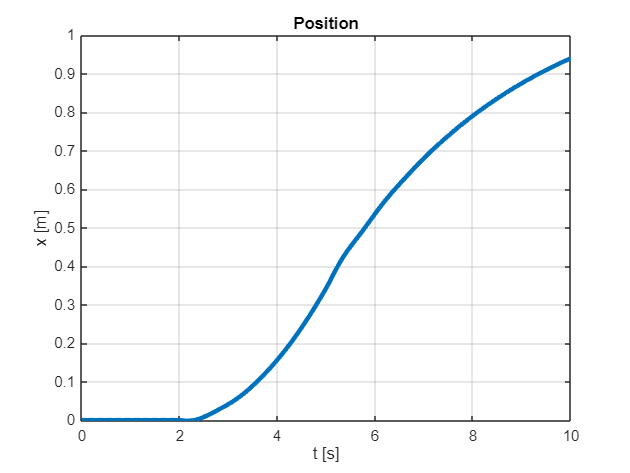

% Time vector
t = 0:0.01:10;
Tsim = 10;

% Speed input
v_ref = zeros(size(t));     
v_ref(t >= 2 & t <= 5) = 2;

input_signal = [t' v_ref'];

out = sim("complete/complete_robot_sim.slx");

x_v = out.simout.signals.values(:,1); 
dx_v = out.simout.signals.values(:,2); 
theta_v = out.simout.signals.values(:,3);
dtheta_v = out.simout.signals.values(:,4);
theta_mes = out.theta_measure.signals.values();
torque_v = out.torque.signals.values();
domega = out.domega.signals.values();
ddx = out.ddx.signals.values(1,:);
t_v = out.tout;

% x
figure;
plot(t_v, x_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('x [m]');
title('Position');
grid on;

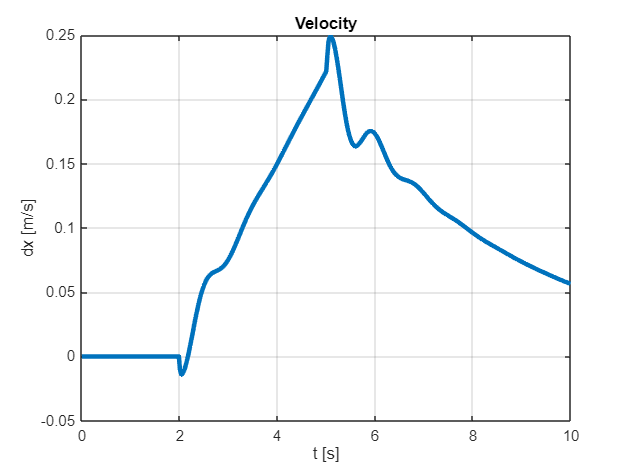


% dx
figure;
plot(t_v, dx_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('dx [m/s]');
title('Velocity');
grid on;

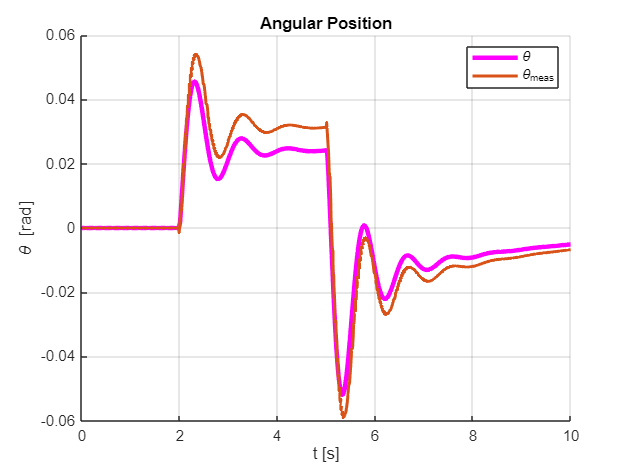



% theta
figure;
hold on;
plot(t_v, theta_v, "LineWidth", 3,"Color","magenta","DisplayName","\theta");

plot(t_v, theta_mes, 'LineWidth', 2,"DisplayName","\theta_{meas}");
xlabel('t [s]');
ylabel('\theta [rad]');
title('Angular Position');
legend('show');
grid on;

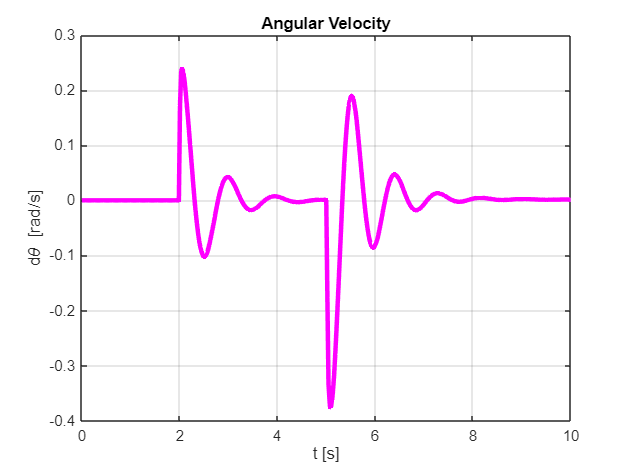


% dtheta
figure;
plot(t_v, dtheta_v, "LineWidth", 3,"Color","magenta");
xlabel('t [s]');
ylabel('d\theta [rad/s]');
title('Angular Velocity');
grid on;

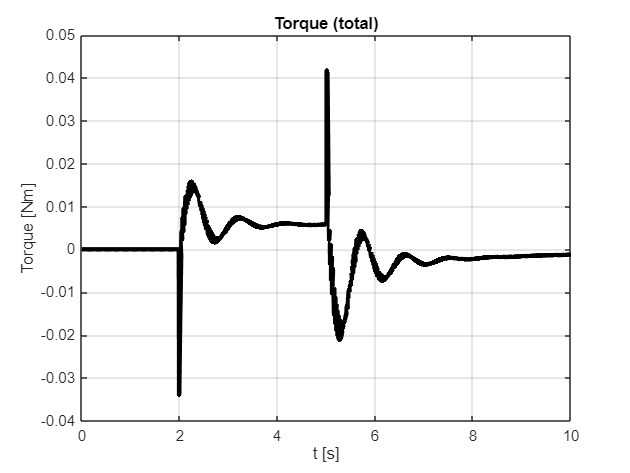


figure;
plot(t_v, torque_v, "LineWidth", 3,"Color","black");
xlabel('t [s]');
ylabel('Torque [Nm]');
title('Torque (total)');
grid on;

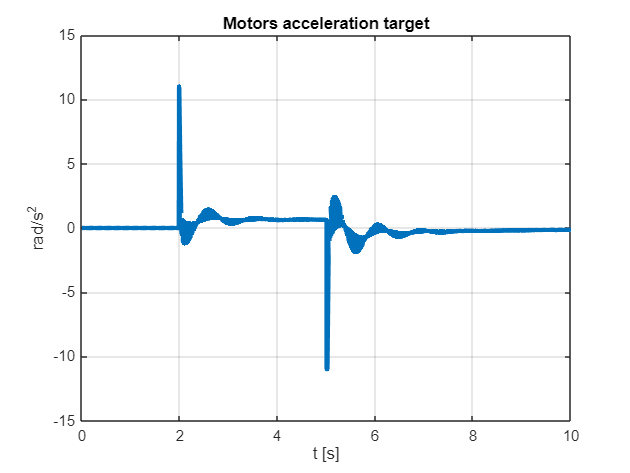


figure;
plot(t_v, -domega*r, "LineWidth", 3);

xlabel('t [s]');
ylabel('rad/s^2');
title('Motors acceleration target');
grid on;

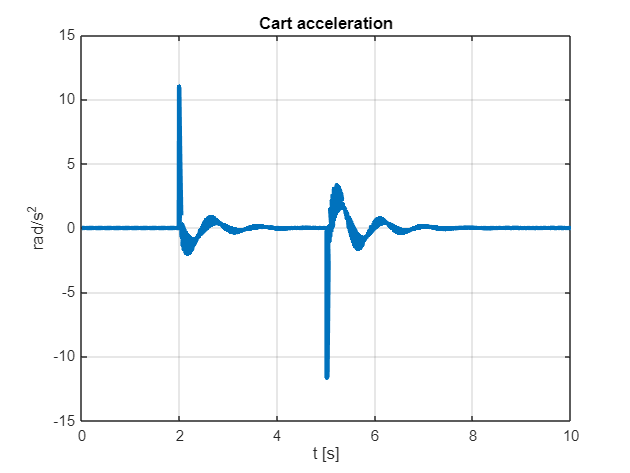


figure;
plot(t_v, ddx, "LineWidth", 3);
xlabel('t [s]');
ylabel('rad/s^2');
title('Cart acceleration');
grid on;